# **IO204 - Digital Loopback**

This example demonstrates a simple communication between two digital inputs and outputs present on the IO204.

The IO204 is a digital I/O module providing 16 24 V inputs (input channel group) and 16 24 V/0.5 A outputs (output channel group).

This module is available with either high- or low-side switches on the digital outputs.

The Read and Write blocks always act on the entire channel group (input or output).

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one IO204 I/O module installed

- Connector cable from the I/O module to the terminal board

- 68-pin terminal board with jumper wires

### Test Setup

There are two possible wiring configurations for this test. This depends on whether you have the IO204-HS (High Side switches) or the IO204-LS (Low Side switches). In order for this example to work, make sure you know which IO204 version is in your system. Both possible wiring configurations are listed below:

#### High-Side Test Wiring

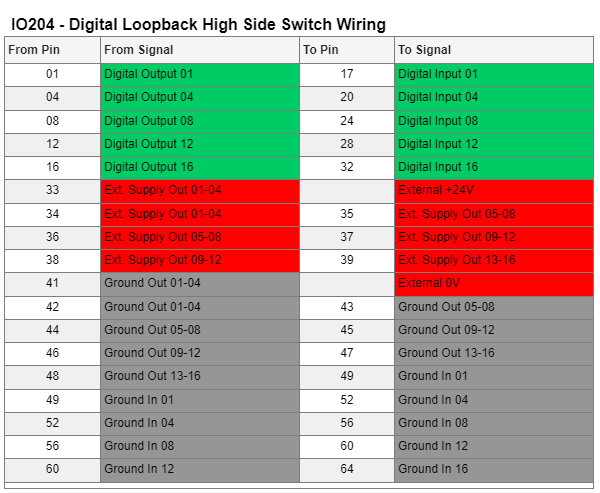

#### Low-Side Test Wiring

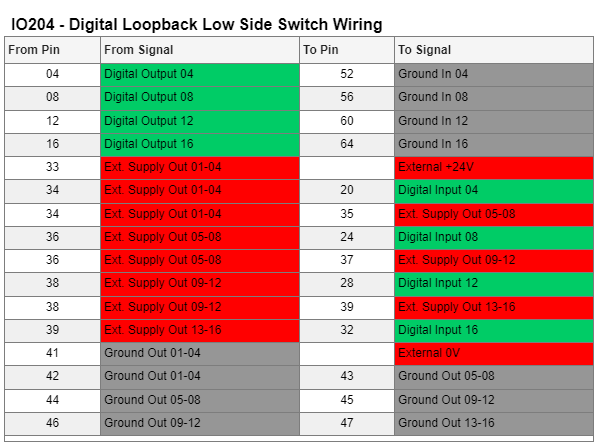

[IO204 Pin Mapping](https://www.speedgoat.com/help/slrt/page/io_main/refentry_io204_pin_mapping)

## Initialize and Open the Simulink model

 
% Open Simulink Model
modelName = 'sgMdl_IO204_DigitalLoopback';
open_system(modelName);

### Model Description

The Simulink model features the IO204 Setup, Digital Input and Digital Output blocks.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model.

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
stoptime = 2;
pause(stoptime)
tg.stop;

% Number of signals to be viewed in the SDI
numsignals = 5; 
pause(1)

Simulink.sdi.clearAllSubPlots;
Simulink.sdi.view;
runobj = Simulink.sdi.Run.getLatest;
sigsobj = runobj.getAllSignals;
for k = 1:numsignals % Display all signals in the plot
    sigsobj(k).Checked = 1;
end

pause(1)
Simulink.sdi.setSubplotLimits(1, 1, "tMin", 0, "tMax", stoptime, "yMin", -0.5, "yMax", 7.5);

### Check the Results

The output is then visible in the Simulink Data Inspector (SDI). You should see 5 square waves, like in the image below:

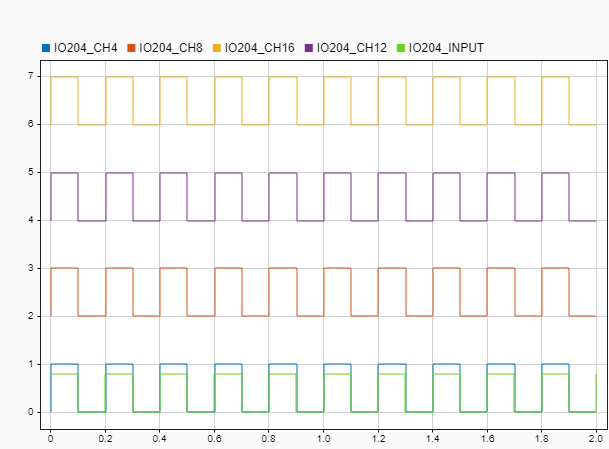

The input signal is represented by the square wave with an amplitude of 0.8.  If you zoom on the bottom signals, you will notice that the input signal and the channel 4 signal have a small phase shift. This is due to the simulation step time that creates a shift for each signal that passes through a Simulink block.

## Additional References

- [IO204 examples and documentation](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_io204)